close all;clear variables; clear functions; %#ok<CLFUNC>
set(groot,'defaultAxesFontSize',18)

# Initialize

### Plotting parameters

global mindB nInterp n_plot plotLthru  plotImpedance plotHighlight plotParameterAnnotations

mindB = -25;
nInterp = 50;
n_plot = 0;
plotHighlight = 1; %Highlight ith filterbank design (ith filter from top) (zero for no highlighting)


plotImpedance           = 0;
plotParameterAnnotations= 0;

plotLthru               = 1;

FB_names = {};

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 4e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0;


nFilters    = 1;
f0          = 220e9;

% TL-Impedances
Z0_KID      = 54.81;
Z0_skyline  = 79.04;

singleFilterPlot = nFilters; 

### Error properties

lres_error = [1 1 1 1 1];%[1 1.002 1.003 1.004];%
kc_error = [1 0.992 0.996 1.004 1.008];%ones(size(lres_error));%[1 0.996 0.992 1.004 1.008];%ones(size(lres_error));%[1 0.996 0.992 0.988];%[1 1.004 1.008 1.012];
C_coup_KID_error = ones(size(lres_error));%[1 0.85 0.90 1.1 1.15];
C_coup_thru_error = ones(size(lres_error));%[1 0.85 0.90 1.1 1.15];
L_lambda4_error = ones(size(lres_error));%[1 0.6 0.8 1.2 1.4];%
L_3lambda4_error = ones(size(lres_error));%[0.9 1 1.1 1.2];
error_matrix = [lres_error; kc_error; C_coup_KID_error; C_coup_thru_error; L_lambda4_error; L_3lambda4_error];
error_element = 2;

## Directional filter

Q = 100


Q = 58


Q = 82


Q = 76


Q = 55


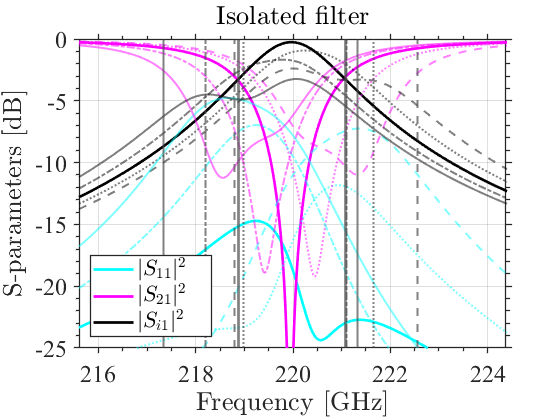

for i=1:length(kc_error)
    [ABCD_SingleToTermination,ABCD_SingleToMKID] = ToleranceDirectionalFilter(f,f0,Z0_skyline,Z0_KID,Ql_target,Qi,ThruLineLosses,sep,singleFilterPlot,error_matrix(:,i),error_element);
    
    n_plot = n_plot + 1;
    FB_names{n_plot} = sprintf('%0.5g%%',100.*error_matrix(2,i));
    
    showSingleFilter(f,f0,ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target);
end

% 
% [ABCD_SingleToTermination,ABCD_SingleToMKID] = ToleranceDirectionalFilter(f,f0,Z0_skyline,Z0_KID,Ql_target,Qi,ThruLineLosses,sep,singleFilterPlot,lres_error,kc_error,error_filter);
% 
% n_plot = n_plot + 1;
% FB_names{n_plot} = 'Directional Filter';
% 
% 
% showSingleFilter(f,f0,ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)


### Error properties

% lres_error = [1 1 1 1 1];%
% kc_error = [1 0.992 0.996 1.004 1.008];%ones(size(lres_error));%[1 0.998 0.997 0.996];%[1 0.996 0.992 0.988];%
% C_coup_KID_error = ones(size(lres_error));%[1 0.85 0.9 1.1 1.15];%
% C_coup_thru_error = ones(size(lres_error));%[1 0.95 0.9 0.85];
% C_coup_refl_error = ones(size(lres_error));%[1 1.002 1.003 1.004];
% L_lambda4_error = ones(size(lres_error));%[1 0.6 0.8 1.2 1.4];%
% error_matrix = [lres_error; kc_error; C_coup_KID_error; C_coup_thru_error; C_coup_refl_error; L_lambda4_error];
% error_element = 2;

## Reflector filter

% for i=1:length(kc_error)
%     [ABCD_SingleToTermination,ABCD_SingleToMKID] = ToleranceReflectorFilter(f,f0,Z0_skyline,Z0_KID,Ql_target,Qi,ThruLineLosses,sep,singleFilterPlot,error_matrix(:,i),error_element);
%     
%     n_plot = n_plot + 1;
%     FB_names{n_plot} = sprintf('%0.5g%%',100.*error_matrix(2,i));
%     
%     showSingleFilter(f,f0,ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target);
% end

% [ABCD_SingleToTermination,ABCD_SingleToMKID] = ToleranceReflectorFilter(f,f0,Z0_skyline,Z0_KID,Ql_target,Qi,ThruLineLosses,sep,singleFilterPlot,lres_error,kc_error,error_filter);
% 
% n_plot = n_plot + 1;
% FB_names{n_plot} = 'Reflector filter';
% 
% 
% showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)


## Deshima filter

% [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter,idealPeakTransfer] = DeshimaFilter(f,f0,Z0_skyline,Z0_KID,Ql_target,Qi,ThruLineLosses,sep,singleFilterPlot);
% 
% n_plot = n_plot + 1;
% FB_names{n_plot} = 'Manifold filter';
% 
% 
% showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
% showPower(f,f0,ABCD_FilterBank,ABCD_EachFilter,Z0_skyline,Z0_KID,Ql_target,idealPeakTransfer)
% % showDimensions(f,f0,l_thru)

## Figure formatting

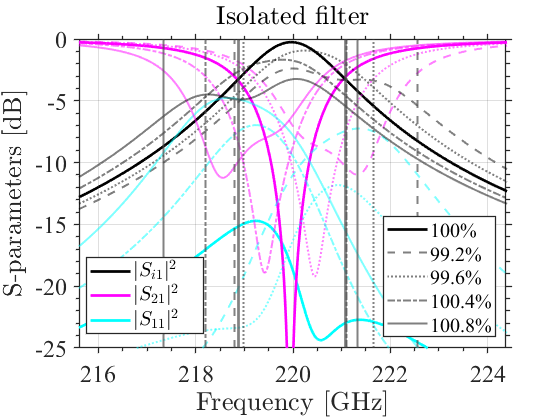

if n_plot <= 1
    formatColorfulMetrics()
else
    formatLegends(FB_names)
end

% Format font size of figure legends
lh = findall(0,'Type','Legend');
set( findall(lh, '-property', 'fontsize'), 'fontsize', 15)


% optional markers in figure 1
if plotParameterAnnotations
    fHandle = figure(1); %#ok<UNRCH> 
    set(findall(fHandle,'Type','constantline'),'linestyle','--','linewidth',2,'alpha',0.5)
end

% clear variables